## Plot throughput_vs_N based on  `Gamma NF`

clc
clear all
close all

theta_throughput_vs_N = []; 

for i = 1:2:15
    num_bit = 1;
    UAV_N = i;
    num_iteration = 1e03;
    freq = 2e09; % GHz
    R = 3;
    
    p_dbm = [18, 20, 22];
    p_db = p_dbm - 30;
    p = 10.^(p_db/10);
    
    sigma_2_db = -24;
    
    gamma_NF_db = p_db - sigma_2_db;
    gamma_NF = 10.^(gamma_NF_db/10);
    gamma_th = 6e-09;
    
    m_AU = 2;
    omega_AU = 1;
    m_UB = 1;
    omega_UB = 2;
    
    pl_exponent = 2; % for LOS
    
    GU_A_coor = [-600, 0, 0];
    GU_B_coor = [+600, 0, 0];
    UAV_H = 100; % meter
    
    coor = [-500:5:500];
    UAVs_coor = reshape(coor(randperm(size(coor,2), UAV_N*2)), [UAV_N, 2]);
    
    UAVs_coor = cat(2, UAVs_coor, repmat(UAV_H, [UAV_N, 1]));
    Troughput_prob = zeros(1,length(gamma_NF_db));
    
    parfor gamma_NF_index = 1:length(gamma_NF_db)
        Troughput_sum = 0;
%         x_num = 0;
        for iter = 1:num_iteration
            fading_AU = repmat(random('nakagami', m_AU, omega_AU, [1, num_bit]), 1, UAV_N);
            fading_UB = repmat(random('nakagami', m_UB, omega_UB, [1, num_bit]), 1, UAV_N);
            
            dist_AU = vecnorm((repmat(GU_A_coor, UAV_N,1) - UAVs_coor)');
            dist_UB = vecnorm((repmat(GU_B_coor, UAV_N,1) - UAVs_coor)');
            path_loss_AU = ((3e08/(4*pi*freq))^2) * (dist_AU.^(-pl_exponent));
            path_loss_UB = ((3e08/(4*pi*freq))^2) * (dist_UB.^(-pl_exponent));
            
            h_AU = fading_AU .* sqrt(path_loss_AU);
            h_UB = fading_UB .* sqrt(path_loss_UB);
            
            gamma_AU = (abs(h_AU).^2)*gamma_NF(gamma_NF_index);
            gamma_UB = (abs(h_UB).^2)*gamma_NF(gamma_NF_index);
            
%             c = gamma_AU > gamma_th;
            c = 1;

            theta_i = gamma_UB .* c;
            % Selection
            [argvalue, argmax] = max(theta_i);
            
            selected_uav = argmax;
            selected_uav_coor = UAVs_coor(selected_uav, :);
            
            gamma_hat_AU = omega_AU * path_loss_AU * gamma_NF(gamma_NF_index)/m_AU;
            gamma_hat_UB = omega_UB * path_loss_UB * gamma_NF(gamma_NF_index)/m_UB;
            
            selected_uav_theta = argvalue;
%             if selected_uav_theta <= gamma_th
%                 x_num = x_num + 1;
%                 continue
%             end
            theta_CDF_each = theta_CDF(gamma_th, gamma_hat_AU ,gamma_hat_UB, m_AU, m_UB);
            theta_CDF_prod = prod(theta_CDF_each);
            Troughput_sum = Troughput_sum + (1 - theta_CDF_prod) * (R/2);
        end
        Troughput_prob(gamma_NF_index) = Troughput_sum / (num_iteration);
    end
    disp(i)
    theta_throughput_vs_N = [theta_throughput_vs_N ; Troughput_prob];
end

     1

     3

     5

     7

     9

    11

    13

    15



save('result/theta_throughput_vs_N', 'theta_throughput_vs_N');

figure()
plot([1:2:15], theta_throughput_vs_N,'-*')
% plot(gamma_NF_db, theta_throughput_vs_N_for_n(1,:),'-*')
% hold on
% plot(gamma_NF_db, theta_throughput_vs_N_for_n(2,:),'-*')
% hold on
% plot(gamma_NF_db, theta_throughput_vs_N_for_n(3,:),'-*')
% hold on
% plot(gamma_NF_db, theta_throughput_vs_N_for_n(4,:),'-*')
xlabel('\gamma_{NF} (dB)'); ylabel('\tau_{OHM}'); title('throughput_vs_N of HM Base Selection versus \gamma_{NF} (dB)')
h = legend('N=1', 'N=2', 'N=3', 'N=4');

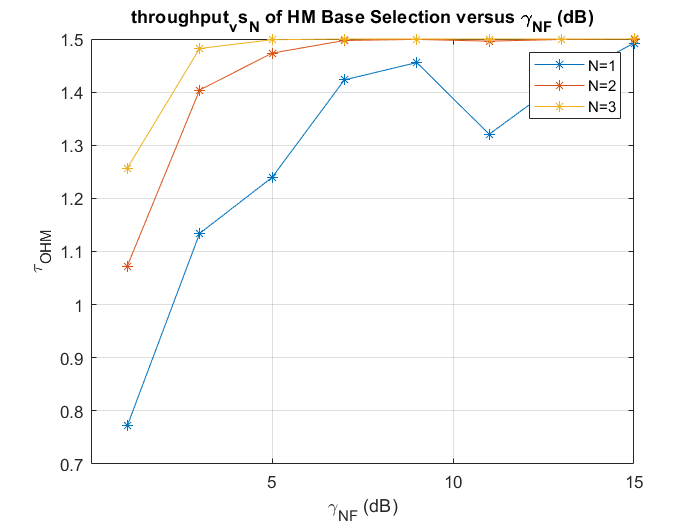

set(h,'Interpreter','none')
grid on, hold on
% ylim([1e-4 1])
xticks(5:5:30)